# Estructuras de datos: Matrices

La estructura de datos más básica de MATLAB es la matriz. Una matriz es un *arreglo rectangular bidimensional* de elementos de datos dispuestos en filas y columnas.

De forma general se puede pensar que casi todo dentro de MATLAB es una matriz, incluso un solo número se almacena como una matriz.

**Observación**

Un *arreglo* (**array** en inglés) y una *matriz* no son lo mismo. Un arreglo es una colección o grupo de objetos (datos, variables, etc.) que puede tener distintos tipos de datos y puede tener más de 2 dimensiones, mientras que **una matriz es un tipo de arreglo**, más específicamente es un arreglo homogéneo porque únicamente puede contener elementos del mismo tipo, además que una matriz es *bidimensional*: sólo tiene filas y columnas.

**Figura 1.** Tipos de arreglos.

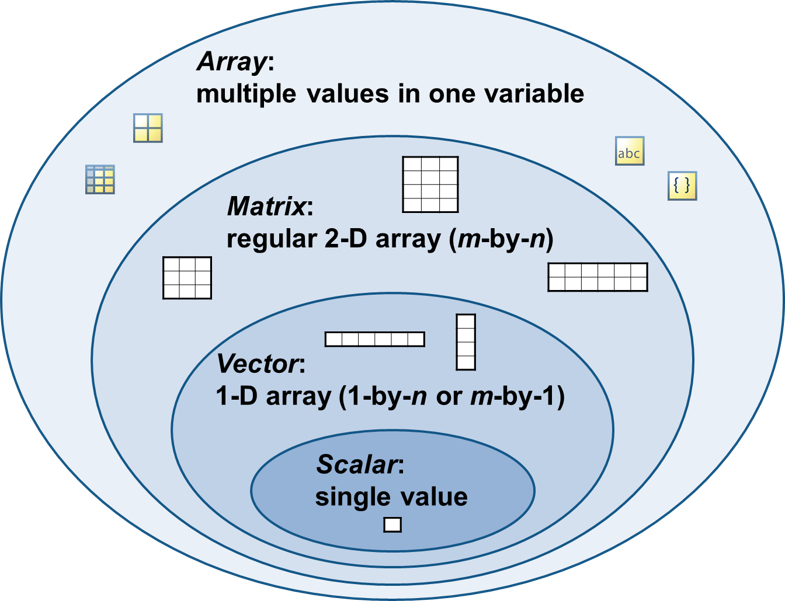

*Tomado de la documentación oficial de MATLAB.*

## Diferencia entre escalar, vector y matriz

Existen 3 conceptos dentro de MATLAB que se debe saber diferenciar bien cuando se trabajan con matrices:

- **Escalar**: matriz de dimensiones $1\times 1$.

- **Vector**: matriz de dimensiones $1\times m$ o $n\times 1$.

- **Matriz**: agrupación de filas y columnas. Es de dimensiones $m\times n$.

### Escalar

Como se mencionó, un escalar posee las dimensiones $1\times 1$.

% Ingrese su código aquí :)

### Vector

Un vector puede ser de dos tipos: **vector fila** ($1\times m$) o **vector columna** ($n\times 1$). La característica que destaca de cada tipo de vector es que posee o bien una sola fila o bien una sola columna.

Ahora que vamos a definir nuestra primera matriz, es importante conocer lo siguiente:

- **Una matriz se define con corchetes** `[]`

- Para separar las columnas se utiliza la coma `,` o se utiliza al menos un espacio en blanco

- Para separar las filas se utiliza el punto y coma `;` o se utiliza un salto de línea

% Ingrese su código aquí :)

**Observación:** Es posible crear un vector columna a través de un vector fila. Esto se realiza añadiendo el operador de transposición (un apóstrofo `'`) al final del vector fila.

% Ingrese su código aquí :)

### Matriz

Para crear una matriz utilizamos tanto `;` como `,` para separar las filas y columnas, respectivamente. Por ejemplo, se tiene la siguiente matriz:


$$A=\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
4 & 5 & 6\\
7 & 8 & 9
\end{array}\right\rbrack$$


Ahora creémosla dentro de MATLAB. Esto se realiza a partir de las filas.

% Ingrese su código aquí :)

Notemos que primero se crea la fila $\left\lbrack 1\;2\;3\right\rbrack$, luego se crea la fila $\left\lbrack 4\;5\;6\right\rbrack$ y finalmente se crea la fila $\left\lbrack 7\;8\;9\right\rbrack$. Y estas filas están separadas por el punto y coma `;`.

#### Observación

Siempre se debe recordar que una matriz es un arreglo ordenado rectangular (mediante filas y columnas), por ende, si se crea una matriz con una fila de 4 elementos y otra fila de 3 elementos, entonces obtendremos un error.


$$A=\left\lbrack \begin{array}{cccc}
1 & 2 & 3 & 4\\
5 & 6 & 7 & ?
\end{array}\right\rbrack$$


En la forma incorrecta nos falta un elemento para que la matriz esté completa, por eso ocurre el error. En ese espacio $?$ debería ir algún valor para que la matriz se cree sin problemas.

### Matriz vacía

Antes de continuar es menester conocer la matriz vacía. Esta matriz se caracteriza por no tener elementos, atributo que le da su nombre.

Para crear una matriz vacía se utiliza la función `empty`, pero de una manera ligeramente diferente a como hemos trabajado hasta este momento.

Es decir, se debe utilizar la *notación punto* indicando el nombre del tipo de dato (o clase) y luego que se trata de una matriz vacía.

% Ingrese su código aquí :)

#### Observación

Esta matriz se puede presentar de diferentes formas, no únicamente por dos corchetes sin elementos. Esto dependerá del tipo de dato con el que se esté trabajando, pero es más que suficiente con leer qué tipo de matriz se obtiene. Cuando es una matriz vacía MATLAB suele indicar que se trata de una, además del tipo de matriz.

### Notación científica en matrices

Previamente estudiamos la notación científica dentro de MATLAB, pero ese estudio fue para escalares. Cuando se trata de matrices es ligeramente diferente. La diferencia radica en la visualización de la notación científica de una matriz.

% Ingrese su código aquí :)

Por defecto, la notación científica de una matriz siempre se visualizará cuando al menos uno de los elementos de ésta sea muy grande o muy pequeño.

## Crear vectores con el operador dos puntos y la función `linspace`

Es posible crear vectores **linealmente espaciados** con el *operador dos puntos,* `:`,o con la función `linspace`. Sin embargo, se debe diferenciar cuánto utilizar un método u otro.

**Figura  2.** Operador dos puntos VS. Función `linspace`.

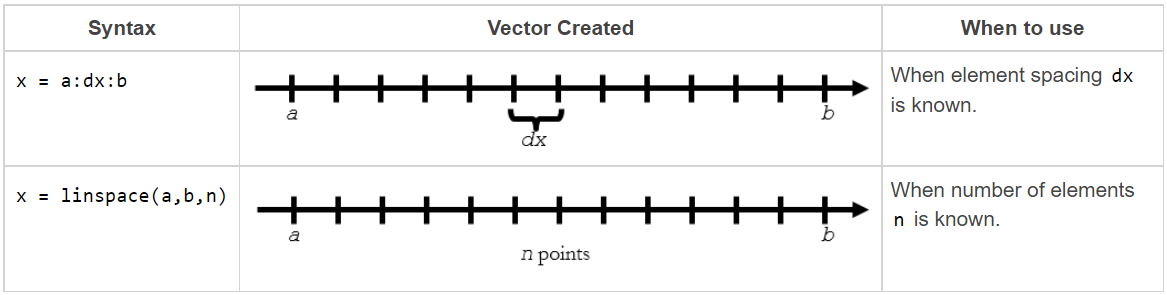

*Tomado de la documentación oficial de MATLAB.*

### Operador dos puntos `:`

El operador dos puntos `:` permite crear vectores linealmente espaciados conociendo:

- el número inicial

- el número final

- el espaciamiento

Lo que se desconoce a priori con el operador dos puntos `:` es el número de elementos.

% Ingrese su código aquí :)

#### Ejemplo

La serie de Taylor de la función $e^x$ se define como


$$1+x+\frac{x^2 }{2}+\frac{x^3 }{3!}+\frac{x^4 }{4!}+\frac{x^5 }{5!}+\ldotp \ldotp \ldotp$$


Sumar los primeros 10 elementos de la serie para $x=1$.

**Nota:** Utilizar el siguiente bloque de código, donde únicamente falta definir los términos de la suma.

El código completo, junto con los temas relacionados, se irá explicando a lo largo del curso. Por el momento es necesario enfocarse en la creación de vectores linealmente espaciados.

#### Solución

% Ingrese su solución aquí :)

#### Observaciones

- Si no se indica el espaciamiento, entonces MATLAB asume que es 1.

% Ingrese su código aquí :)

- Si los números generados con el espaciamiento indicado no llega exactamente al número final, entonces tomará el número anterior al número final que sí cumpla con el espaciamiento.

% Ingrese su código aquí :)

- Si el espaciamiento o numero final es inadecuado, es decir, no hay números entre el número inicial y número final con el espaciamiento indicado, entonces el resultado es la matriz tipo `double` vacía.

% Ingrese su código aquí :)

### Función `linspace`

La función `linspace` permite crear vectores linealmente espaciados conociendo:

- el número inicial

- el número final

- el número de elementos

Lo que se desconoce a priori con la función `linspace` es el espaciamiento.

% Ingrese su código aquí :)

#### Ejemplo

Visualizar el área bajo la curva de la función $\sqrt{x}$ desde $0$ hasta $2$.

**Nota:** Utilizar el siguiente bloque de código, donde únicamente falta definir los términos de la suma.

El código completo, junto con los temas relacionados, se irá explicando a lo largo del curso. Por el momento es necesario enfocarse en la creación de vectores linealmente espaciados.

#### Solución

% Ingrese su solución aquí :)

#### Observaciones

- Si no se indica el número de elementos, MATLAB que es 100.

% Ingrese su código aquí :)

- Además, el número final siempre es el último número del vector creado con esta función, a diferencia del operador dos puntos, `:`, donde no necesariamente el número final estará en el vector creado. 

### Función `logspace`

La función `logspace` permite crear vectores logarítmicamente espaciados (en base 10) conociendo:

- la potencia del número inicial

- la potencia del número final

- el número de elementos

Es decir, si se quisieran cierta cantidad de números logarítmicamente espaciados en base 10 con el número inicial ${10}^0$ hasta el número final ${10}^4$, entonces la potencia del número inicial es $0$ y la potencia del número final es $4$.

Lo que se desconoce a priori con la función `logspace` es el espaciamiento.

% Ingrese su código aquí :)

#### Observación

- Si no se indica el número de elementos, MATLAB que es 100.

% Ingrese su código aquí :)

### Dimensión predominante en una matriz

La dimensión predominante, o principal, cuando se trabaja con matrices es la columna (o también se le llama dimensión `1`). Luego de la dimensión predominante se encuentra la fila (dimensión secundaria), o dimensión `2`. Si se trabaja con vectores esto no es importante, pero con matrices $m\times n$ sí debe considerarse.

Por ejemplo, veamos qué ocurre con la función `sum` (suma) cuando se aplica a vectores y matrices.

% Ingrese su código aquí :)

#### Observación

Casi todas las funciones dentro de MATLAB trabajarán con las columnas como dimensión predominante y las filas como dimensión secundaria, pero existen ciertas excepciones que trabajarán con las filas como dimensión predominante y las columnas como dimensión secundaria.

Un ejemplo de estas excepciones es la función `circshift`.

#### Observación

Evidentemente se debe considerar esto dependiendo de lo que se requiera realizar, además de si la función utilizada permite o no el cálculo en otras dimensiones.

Por ejemplo, la función `sqrt` (raíz cuadrada) no permite calcular en ninguna dimensión. Esta función directamente aplica la raíz cuadrada a cada elemento de la matriz.

% Ingrese su código aquí :)

Aunque bueno, ¿cuál sería el objetivo de hacer una raíz cuadrada por columna o fila únicamente? Nunca está demás leer un poco de la documentación de una función para conocer las capacidades y limitaciones de ésta.

#### Ejemplo

El archivo "`Tema03_Auxiliar_TemperaturaMediaMensual.mat`" contiene información acerca de la temperatura media mensual (ºC) desde el 2003 hasta el 2006 (columnas) para cada mes del año (filas), de una estación meteorológica.

¿Cuál es el promedio de la temperatura media mensual para cada año? ¿Cuál es la temperatura medial mensual máxima de cada mes a lo largo de los 4 años?

**Nota:** Utilizar las funciones `mean` para el promedio y `max` para el máximo.

#### Solución

% Ingrese su solución aquí :)

## Determinar las dimensiones y el número de elementos

Cuando tenemos una matriz es impotante saber cuáles son sus dimensiones, además de cuántos elementos hay en esta matriz. A continuación se presentan las funciones para este fin.

### Funciones `size` y `length`

La función `size` permite conocer las dimensiones de una matriz.

% Ingrese su código aquí :)

El primer número representa el número de filas y el segundo número representa el número de columnas.

Por otra parte, la función `length` devuelve el valor de la dimensión más grande.

% Ingrese su código aquí :)

La función `length` es especialemente útil cuando se trabajan con vectores, puesto que la dimensión más grande coincide con el número de elementos del vector. No obstante, cuando se quiere conocer cuál es el valor de la dimensión más grande únicamente, también resulta bastante útil.

### Función `numel`

La función `numel` permite conocer el número de elementos dentro de una matriz.

% Ingrese su código aquí :)

### Ejemplo

A continuación se muestra un sistema de ecuaciones $3\times 3$,


$$\begin{array}{l}
5x_1 +2x_2 +9x_3 =-10\\
{-2x}_1 +{8x}_2 +{9x}_3 =0\\
{-8x}_1 +{3x}_2 -x_3 =-2
\end{array}$$


Determinar el número de elementos de la matriz de coeficientes sin utilizar la función `numel`.

### Solución

% Ingrese su solución aquí :)

## Concatenar matrices

Teniendo en cuenta las dimensiones de las matrices, es posible concatenar (unir) una o más matrices siempre y cuando el resultado sea una matriz $m\times n$.

**Para concatenar matrices también se utilizan corchetes** `[]`.

**Figura 3.** Concatenación horizontal.

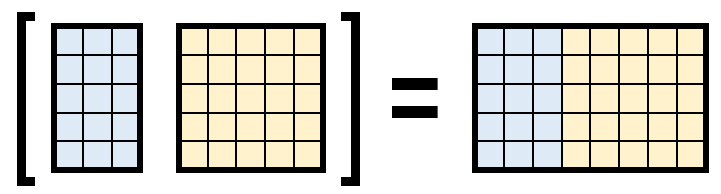

% Ingrese su código aquí :)

**Figura 4.** Concatenación vertical.

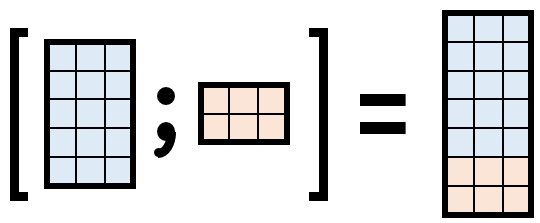

% Ingrese su código aquí :)

**Figura 5.** Concatenación combinada.

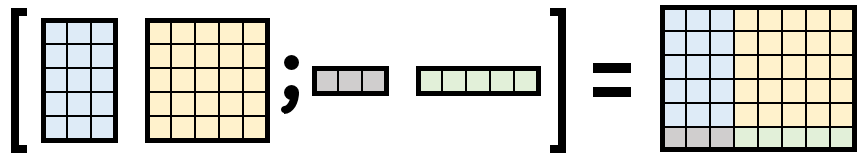

*Todas las figuras fueron tomadas de de la documentación oficial de MATLAB.*

% Ingrese su código aquí :)

## Redimensionar matrices

Muchas funciones en MATLAB pueden tomar los elementos de una matriz existente y colocarlos en una forma o secuencia diferente. Esto puede ser útil para preprocesar los datos para cálculos posteriores o analizar los datos.

**Figura 6.** Redimensionamiento de una matriz.

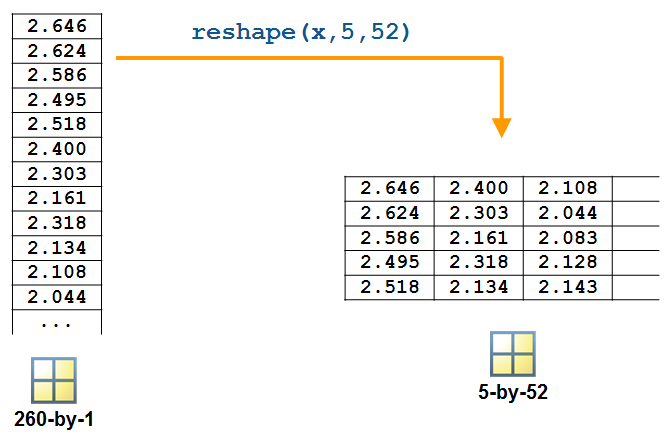

*Tomado de la documentación oficial de MATLAB.*

### Función `reshape`

La función `reshape` permite redimensionar una matriz.

Lo que se debe considerar es que la nueva matriz redimensionada debe contener a todos los elementos de la matriz original. Es decir, el producto de las dimensiones de cualquier matriz redimensionada debe ser igual al producto de las dimensiones de la matriz original.

Por ejemplo, en lugar de tener una matriz $6\times 4$ se podría redimensionar a una matriz $8\times 3$.

% Ingrese su código aquí :)

#### Observación

En realidad, si el arreglo es bidimensional (una matriz), es más que suficiente especificarle una dimensión a la función `reshape` para que ésta infiera la otra dimensión. Lo que se debe tener en cuenta es que la dimensión especificada tiene que ser un múltiplo del producto de las dimensiones de la matriz original.

% Ingrese su código aquí :)

### Funciones `flipud` y `fliplr`

La función `flipud` permite voltear una matriz de arriba hacia abajo (**flip** **u**p to **d**own), mientras que la función `fliplr` permite voltear una matriz de izquierda a derecha (**flip** **l**eft to **r**ight).

% Ingrese su código aquí :)

### Ejemplo

La función `magic` permite crear una matriz mágica. Una matriz mágica se caracteriza porque la suma de cada una de sus filas, columnas y diagonal principal y secundaria es igual.

Crear una matriz mágica $5\times 5$ y verificar que realmente lo sea.

### Solución

% Ingrese su solución aquí :)

## Ordenar matrices

Ordenar los datos en una matriz también es una herramienta valiosa y MATLAB ofrece varios enfoques.

### Función `sort`

La función `sort` permite ordenr los elementos de cada fila o columna de una matriz **por separado** en orden ascendente o descendente.

- Si la matriz es un vector, entonces la función `sort` ordenará los elementos del vector.

- Si la matriz es $m\times n$, entonces la función `sort` tratará las columnas de la matriz como vectores y ordenará cada columna por separado.

Además de esto, también se puede indicar a la función `sort`:

- **La dimensión:** columnas `'1'` (por defecto) o filas `'2'`.

- **La dirección:** `'ascend'` (por defecto) o `'descend'`.

**Figura 7.** Dimensiones de una matriz dentro de una función interna.

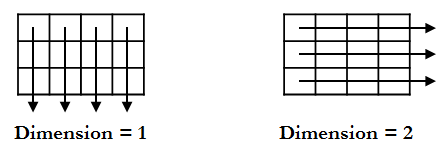

*Tomado de la documentación oficial de MATLAB.*

% Ingrese su código aquí :)

### Función `sortrows`

La función `sortrows` permite ordenar filas o columnas enteras entre sí, en función de una columna de referencia.

Notemos que este es un inconveniente con la anterior función `sort`, puesto que las columnas o filas son tratadas de forma independiente. Si no queremos que se pierda la relación entre fila y columna, es preferible utilizar esta función `sortrows`.

También se puede indicar a la función `sortrows`:

- **La columna de referencia:** depende de cuántas columnas tenga la matriz, pero si no se indica entonces se tomará como referencia la primera columna.

- **La dirección:** `'ascend'` (por defecto) o `'descend'`.

% Ingrese su código aquí :)

### Ejemplo

El archivo "`Tema03_Auxiliar_Supermercado.mat`" contiene una matriz con información de las ventas de un supermercado. La matriz posee cuatro columnas:

- La primera representa el ingreso por cada venta.

- La segunda representa la cantidad de artículos vendidos de cada venta.

- La tercera representa el descuento realizado de cada venta.

- La cuarta representa el beneficio obtenido de cada venta.

¿Cuál es el descuento y beneficio del mayor ingreso de las ventas? ¿Cuál es el ingreso de la venta con mayor beneficio negativo (o pérdida)?

### Solución

% Ingrese su solución aquí :)

#### Observación

Para odernar por columnas en lugar de por filas, bastaría transponer la matriz para el ordenamiento y luego transponer la matriz ordenada para obtener la matriz original ordenada por columnas.

% Ingrese su código aquí :)

## Indexación de matrices

Indexar no es más que acceder a los elementos de una matriz a través de un índice. Aunque algunas formas no necesariamente utilizan índices, también se les conoce como indexación.

En MATLAB existen tres formas principales para acceder a los elementos de la matriz en función de su ubicación (índice) en la matriz. Estos enfoques son la indexación por posición, la indexación lineal (o sencilla) y la indexación lógica.

#### Observación

A continuación se realizarán las explicaciones de cada indexación con matrices numéricas por facilidad. No obstante, la indexación se utiliza con matrices de forma general, por ende, los conceptos que se estudiarán aplican para cualquier tipo de matriz.

### Indexación por posición

Analicemos la siguiente matriz.


$$A=\left\lbrack \begin{array}{ccc}
4_{1,1}  & 8_{1,2}  & 0_{1,3} \\
9_{2,1}  & 2_{2,2}  & 1_{2,3} \\
7_{3,1}  & 5_{3,2}  & 6_{3,3} 
\end{array}\right\rbrack$$


Observemos los índices de cada elemento. Pues bien, se pueden utilizar estos índices (también llamados subíndices) para indexar una matriz por posición. Al igual que la notación matemática, el primer índice indica el número de fila y el segundo índice indica el número de columna.

Es posible indexar:

- **Un único elemento:** Se indican los índices de posición del elemento.

- **Submatrices:** Se indican los índices de las filas y columnas que será extraídas.

- **Filas enteras:** Se indica el índice de la fila o filas, y para las columnas se escribe como índice el operador dos puntos `:`. 

- **Columnas enteras:** Se indica el índice de la columna o columnas, y para las filas se escribe como índice el operador dos puntos `:`.

El operador dos puntos `:` como índice vendría a significar **"todos los elementos"**. También se puede indexar desde un índice hasta otro, indicando un vector linealmente espaciado con índices enteros mayores que cero, en lugar de escribir cada índice manualmente. 

% Ingrese su código aquí :)

Ahora bien, un detalle a tener en cuenta es que los índices siempre son números enteros, matemáticamente hablando. No tendría sentido indexar la fila 1.5 y la columna 2.3, ¿verdad?

Por cierto, ¿cuál sería el resultado del siguiente código?

### Ejemplo

El archivo "`Tema03_Auxiliar_Supermercado.mat`" contiene una matriz con información de las ventas y beneficio de un supermercado. La matriz que contiene el archivo posee cuatro columnas:

- La primera representa el ingreso por cada venta.

- La segunda representa la cantidad de artículos vendidos de cada venta.

- La tercera representa el descuento realizado de cada venta.

- La cuarta representa el beneficio obtenido de cada venta.

Extraer las 1000 ventas con mayor beneficio. Luego, del anterior resultado, extraer el descuento como un vector separado.

### Solución

% Ingrese su solución aquí :)

**Nota:** Utilizando el vector separado que contiene los descuentos de las 1000 ventas con mayor beneficio, se puede utilizar la función `histogram` para generar un histograma con estos datos.

#### Palabra reservada `end`

La palabra reservada `end` en indexación permite hacer referencia al último elemento de una matriz. En síntesis, es un número que hace referencia al último elemento de una matriz, independientemente del tamaño de la matriz o de si ésta cambia sus dimensiones.

% Ingrese su código aquí :)

Se tendría que seguir la misma lógica para obtener algún elemento empezando desde el final.

#### Convertir una matriz en un vector

En el caso de que se necesite convertir una matriz a un vector, se podría indexar fila a fila, o columna a columna, e ir concatenando estas filas, o columnas, para formar el vector. No obstante, el operador dos puntos `:` facilita este trabajo.

Para convertir una matriz en un vector se debe indexar la matriz únicamente con el operador dos puntos `:`.

% Ingrese su código aquí :)

Pero, ¿de qué forma se transforma la matriz en vector? Esto se detalla con la *indexación lineal*.

### Indexación lineal o sencilla

La indexación lineal, o idexación sencilla, se realiza utilizando un único índice, o también denominado *índice sencillo*. Pero, ¿cómo indexar con un único índice? La siguiente imagen muestra el procedimiento que sigue MATLAB para hacer este tipo de indexación.

**Figura 8.** Proceso de indexación sencilla.

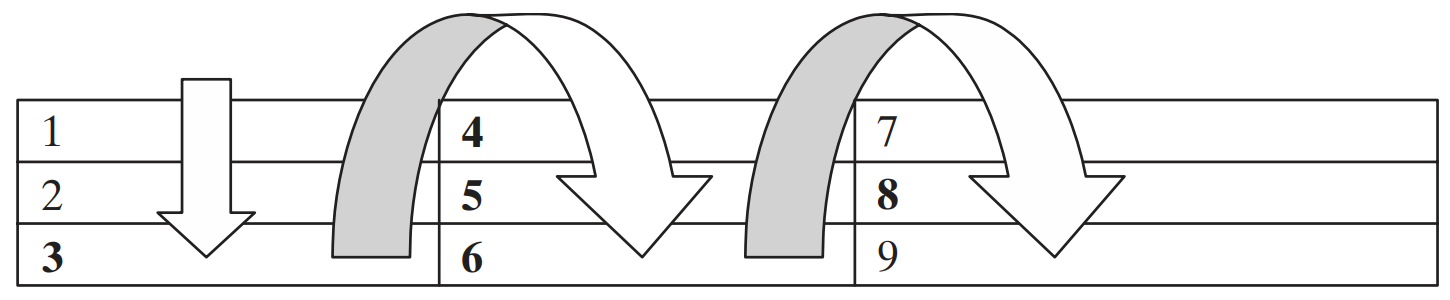

*Tomado de MATLAB para ingenieros de Holly Moore*.

En la anterior figura podemos observar los índices sencillos de una matriz. Es así como funciona el transformar una matriz a un vector `A(:)`, es decir, se apilan las columnas una debajo de otra de derecha a izquierda.

Analicemos la misma matriz anterior con sus índices sencillos:


$$A=\left\lbrack \begin{array}{ccc}
4_1  & 8_4  & 0_7 \\
9_2  & 2_5  & 1_8 \\
7_3  & 5_6  & 6_9 
\end{array}\right\rbrack$$


Con esta indexación únicamente podemos extraer:

- Elementos únicos.

- Vectores fila de elementos indicando los índices sencillos.

- Vectores fila de elementos utilizando el operador dos puntos.

Además, también es posible utilizar la palabra reservada `end` al igual que se hizo con la anterior indexación.

% Ingrese su código aquí :)

### Ejemplo

El archivo "`Tema03_Auxiliar_SistemaSolar.mat`" contiene el nombre, el radio y la masa de los cuerpos celestes del sistema solar.

Cargar la variable que contiene la masa de los cuerpos y ordenarla de mayor a menor, e indexar los 5 cuerpos celestes con menor masa.

**Nota:** Utilizar la palabra reservada `end`.

### Solución

% Ingrese su solución aquí :)

### Indexación lógica

Para el análisis de la indexación lógica se tiene la siguiente figura.

**Figura 9.** Conversión de subíndices a índices.

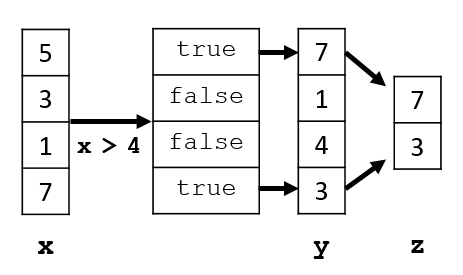

*Tomado de la documentación oficial de MATLAB.*

El uso de valores lógicos es otra forma útil de indexar matrices, especialmente cuando se trabaja con declaraciones condicionales porque se establece una condición y se indexan únicamente los valores que la cumplen.

% Ingrese su código aquí :)

### Relación entre las 3 tipos de indexaciones

Existe una función extremadamente poderosa para determinar índices sencillos, índices por posición y los elementos de éstos índices. Además, se puede utilizar una condición lógica para facilitar búsquedas.

#### Función `find`

La función `find` permite determinar índices y valores de elementos distintos de cero. Aunque su potencial va más allá de esto.

% Ingrese su código aquí :)

#### Ejemplo

El archivo "`Tema03_Auxiliar_SistemaSolar.mat`" contiene el nombre, el radio y la masa de los cuerpos celestes del sistema solar.

Determinar los índices, por posición y lineales, de los radios mayores a 10000 km. Luego, utilizando idexación por posición y lineal, determinar los nombres de los cuerpos celestes que cumple la condición.

**Nota:** Para la condición se debe utilizar la operación relacional "mayor que" `>`.

#### Solución

% Ingrese su solución aquí :)

### Reemplazar elementos de una matriz

Utilizando cualquier tipo de indexación se puede reemplazar elementos de una matriz. Únicamente se indexan los elementos y se asignan los nuevos valores.

% Ingrese su código aquí :)

Esto funciona tanto para reemplazar un único elemento o varios elementos. Lo que se debe considerar es que la matriz que se indexa debe ser del mismo tamaño (tener las mismas dimensiones) que la matriz que reemplazará a la matriz indexada.

% Ingrese su código aquí :)

### Expandir una matriz

Una forma de expandir una matriz es concatenarla con otros elementos o matrices. No obstante, mediante indexación también es posible expandir una matriz.

Se debe indicar un índice fuera de rango de la matriz, es decir, que sea más grande que las dimensiones de la matriz y asignarle un valor o valores. Esto forzará a la matriz a expandirse rellenando los elementos en las posiciones que no se hayan asignado nada con ceros.

Lo que siempre se debe tener en cuenta es que la matriz resultante siempre debe ser consistente, dimensionalmente hablando.

% Ingrese su código aquí :)

Ahora bien, ¿cuál sería la matriz resultante del siguiente código?

### Eliminar elementos de una matriz

Para eliminar elementos de una matriz se utiliza la matriz vacía `[]`. Basta con utilizar cualquier indexación e indexar los elementos que se desean eliminar y asignarles la matriz vacía.

% Ingrese su código aquí :)

Esto funciona tanto para eliminar un único elemento o varios elementos. Lo que se debe considerar es que la matriz final debe ser consistente en sus dimensiones.

% Ingrese su código aquí :)

Por cierto, ¿cuál sería la matriz resultante del siguiente código?

## Matrices especiales

Dentro de MATLAB existen algunas funciones que permiten crear matrices con ciertas características, por lo que se las llaman matrices especiales.

### Función `zeros`

La función `zeros` permite crear una matriz $m\times n$ llena de ceros.

% Ingrese su código aquí :)

#### Observación

Si a la función `zeros` se le pasa únicamente un argumento, es decir, el valor de una sola dimensión, entonces se creará una matriz cuadrada llena de ceros del orden del argumento indicado.

% Ingrese su código aquí :)

### Función `ones`

La función `ones` permite crear una matriz $m\times n$ llena de unos.

% Ingrese su código aquí :)

#### Observación

Si a la función `ones` se le pasa únicamente un argumento, es decir, el valor de una sola dimensión, entonces se creará una matriz cuadrada llena de unos del orden del argumento indicado.

% Ingrese su código aquí :)

### Ejemplo

Crear una matriz que contenga el número $\pi$ en todas sus entradas. ¿Existe más de una forma de hacerlo?

### Solución

% Ingrese su solución aquí :)

### Función `diag`

La función `diag` permite crear una matriz diagonal, la cual utilizará el vector ingresado como elementos de la diagonal principal.

% Ingrese su código aquí :)

No obstante, si se le indica un segundo argumento a la función `diag`, el parámetro `k`, la función desplazará la diagonal como se muestra en la siguiente figura. 

**Figura 10.** Parámetro $k$ de la función `diag`.

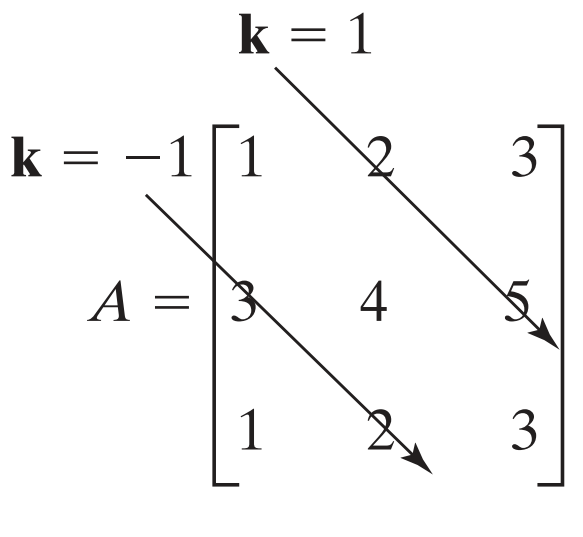

*Tomado de MATLAB para ingenieros de Holly Moore.*

% Ingrese su código aquí :)

#### Observación

Si se pasa como argumento a la función `diag` una matriz en lugar de un vector, entonces esta función extraerá la diagonal de esta matriz. También es posible indicar mediante el parámetro `k` qué diagonal se quiere extraer.

% Ingrese su código aquí :)

## Material adicional

- [Creación, concatenación y expansión de matrices](https://www.mathworks.com/help/matlab/math/creating-and-concatenating-matrices.html)

- [Redimensionar y reorganizar matrices](https://www.mathworks.com/help/matlab/math/reshaping-and-rearranging-arrays.html)

- [Crear arreglos de cadenas](https://www.mathworks.com/help/matlab/matlab_prog/create-string-arrays.html)

- [Operaciones lógicas (o booleanas)](https://www.mathworks.com/help/matlab/logical-operations.html)

- [Indexación de arreglos](https://www.mathworks.com/help/matlab/math/array-indexing.html)

- [Encontrar elementos de una matriz que cumplan una condición](https://www.mathworks.com/help/matlab/matlab_prog/find-array-elements-that-meet-a-condition.html)

- [Función `find`](https://www.mathworks.com/help/matlab/ref/find.html)